# T-S diagram

Here is an example of creating a T-S diagram

% safety first
close all
clear all

% Step 1 download data from BATS and create data vectors
data=xlsread('b10331_ctd.xls');
castid=data(:,1);
lat=data(:,4);
lon=-data(:,5); % the data in in deg W so it should be negative
dep=data(:,6);
p=data(:,7);
t=data(:,8);
sp=data(:,10);

% TEOS-10 calculations
SA=gsw_SA_from_SP(sp,p,lon,lat);
CT=gsw_CT_from_t(SA,t,p);

% define X and Y axes of the T-S diagram
x=linspace(min(SA),max(SA),100);
y=linspace(min(CT),max(CT),101);
[xx,yy]=meshgrid(x,y);

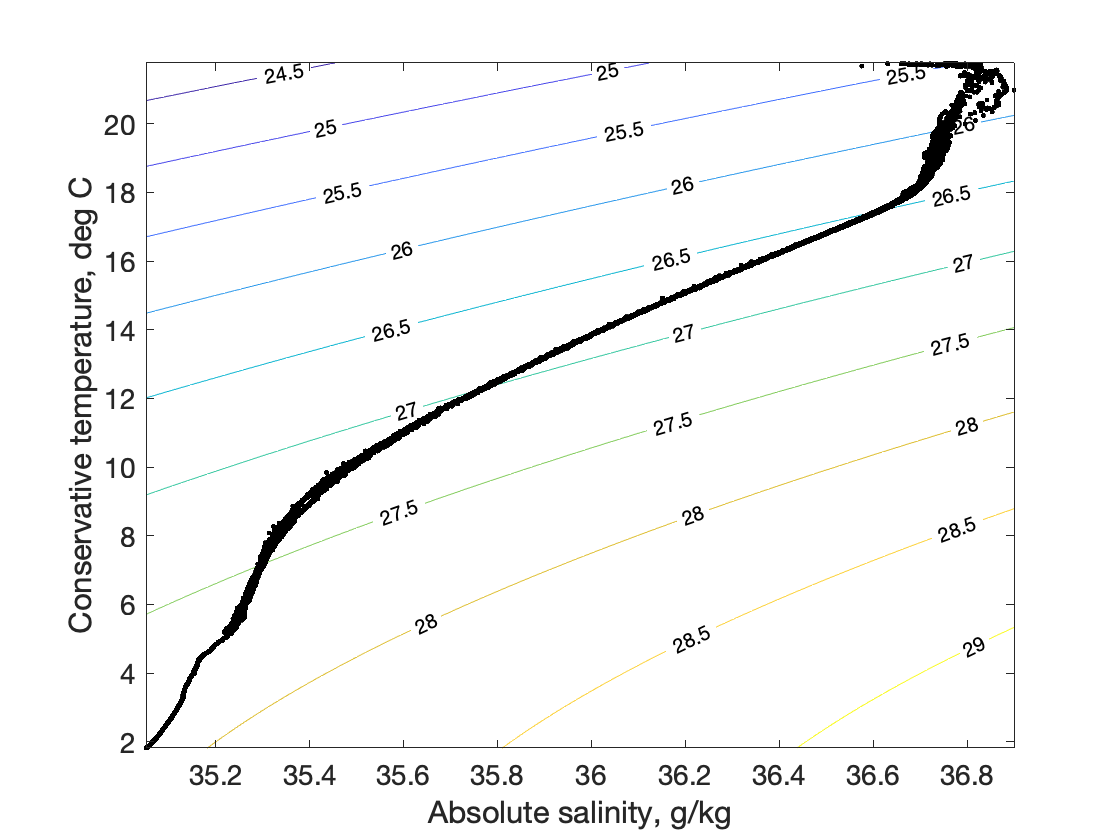

% create sigma-theta array
sig0=gsw_sigma0(xx,yy);
% plot the density contours
figure(1);
[c,h]=contour(xx,yy,sig0,22:.5:29);
clabel(c,h);
xlabel('Absolute salinity, g/kg');
ylabel('Conservative temperature, deg C');
set(gca,'fontsize',14);
hold on;
plot(SA,CT,'k.');